%%%%%%%%%%%%%%%%%%%%%%
%%%figure that shows Diel cycles of AROMA 
%%%created:11/3/22
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", ...
    "Picarro", "VariableNamingRule", "preserve"); %picarro data

cd ..

%SDK AROMA
ppbSDKAROMA = readtimetable("etoAROMA_SDK.xlsx");

%%import met data
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
cd ../../

%%%%%%%%%%%%%%%%%%%%%%
%%% subset Picarro data to August
%%%%%%%%%%%%%%%%%%%%%%

%% Picarroa and AROMA are different time periods of data, so need to justify CRDS comparisons
%% having only August 2021 with a similar humidity diel cycle would show this
inds = isbetween(ppbSDKPicarro.time, datetime(2021, 8, 1), ...
    datetime(2021, 8, 31, 23, 59, 59));
ppbSDKPicarro = ppbSDKPicarro(inds, :);

%%%%%%%%%%%%%%%%%%%%%%
%%%bin by TOD
%%%%%%%%%%%%%%%%%%%%%%

%%use SDK Picarro as reference
numPts = 1; %minimum number of points per bin
numStd = 3; %numbers 3 standard deviations away will be removed
TTsEtO = {ppbSDKPicarro, ppbSDKAROMA(:, 2)}; %ppb eto
TTsHumid = {rawMetSDK(:, end), rawMetSDK(:, end)}; %humidities
timeLims = {[ppbSDKPicarro.Properties.RowTimes(1), ppbSDKPicarro.Properties.RowTimes(end)], ...
    [ppbSDKAROMA.Properties.RowTimes(1), ppbSDKAROMA.Properties.RowTimes(end)]};
structStr = {'SDKPicarro', 'SDKAROMA'};

%%preallocate structure, eto
toPlotEtO = struct;
for i = 1:length(TTsEtO) %ppb eto
    TT = TTsEtO{i}; %current timetable

    %%convert time to fractional days
    times = TT.Properties.RowTimes;
    times = day(times, "dayofyear") + hour(times)/24 + minute(times)/24/60;

    data = timetable2array(TT); %grab eto data

    %%use BinAvgTOD to calculate bins
    [outMean, outStd, outN, outX] = BinAvgTOD(times, data, ...
        1, numPts, numStd, 0, 0);
    %assemble table to put into structure
    Tout = table(outX, outMean, outStd, outN);

    toPlotEtO.(structStr{i}) = Tout; %put into structure
end

%%preallocate structure, humidity
toPlotHumid = struct;
for i = 1:length(TTsHumid) %humidity
    TT = TTsHumid{i}; %current timetable
    times = TT.Properties.RowTimes;
    inds = isbetween(times, timeLims{i}(1), timeLims{i}(2)); %find matching period
    times = times(inds);
    TT = TT(inds, :);
    
    %%convert time to fractional days
    times = day(times, "dayofyear") + hour(times)/24 + minute(times)/24/60;

    data = timetable2array(TT); %grab eto data

    %%use BinAvgTOD to calculate bins
    [outMean, outStd, outN, outX] = BinAvgTOD(times, data, ...
        1, numPts, numStd, 0, 0);
    %assemble table to put into structure
    Tout = table(outX, outMean, outStd, outN);

    toPlotHumid.(structStr{i}) = Tout; %put into structure
end

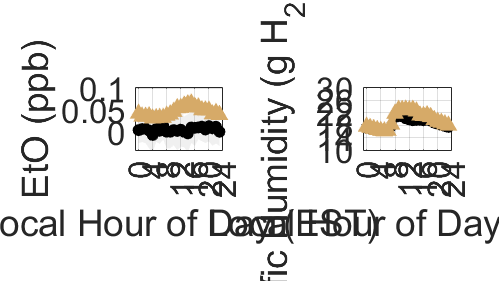

%%%%%%%%%%%%%%%%%%%%%%
%%%plot
%%%%%%%%%%%%%%%%%%%%%%

%%define colors
colors = [0, 0, 0; %picarro
    0.8392, 0.6686, 0.4098]; %SDK AROMA

%%define line types
lineTypes = {'-o', '-^'};
markerSizes = [5, 5.5];
transparencies = [0.06, 0.2];

%%%plot
fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact")

%%1. EtO
ax = nexttile;
hold on
grid on
box on
pbaspect([1.4, 1, 1])

hl = gobjects(length(TTsEtO), 1);

for i = 1:length(TTsEtO)
    toPlotCurrent = toPlotEtO.(structStr{i}); %current line to plot

    %%plot line
    [hl(i), ~] = boundedline(toPlotCurrent.outX, toPlotCurrent.outMean, ...
        toPlotCurrent.outStd, ...
        lineTypes{i}, ...
        'nan', 'gap', 'alpha', 'transparency', transparencies(i), ...
        'color', colors(i, :));
    hl(i).MarkerSize = markerSizes(i); %change line aspects
    hl(i).MarkerFaceColor = colors(i, :);
    hl(i).LineWidth = 4;
end

%%lims and ticks
xlim([-1, 24])
ylim([-0.0414, 0.1014])
xticks(0:4:24)

%%labels
ax.FontSize = 25;
xlabel("Local Hour of Day (EST)")
ylabel("EtO (ppb)")

hold off


%%2. Humidity
ax = nexttile;
hold on
grid on
box on
pbaspect([1.4, 1, 1])

hl = gobjects(length(TTsHumid), 1);

for i = 1:length(TTsHumid)
    toPlotCurrent = toPlotHumid.(structStr{i}); %current line to plot

    %%plot line
    [hl(i), ~] = boundedline(toPlotCurrent.outX, toPlotCurrent.outMean, ...
        toPlotCurrent.outStd, ...
        lineTypes{i}, ...
        'nan', 'gap', 'alpha', 'transparency', transparencies(i), ...
        'color', colors(i, :));
    hl(i).MarkerSize = markerSizes(i); %change line aspects
    hl(i).MarkerFaceColor = colors(i, :);
    hl(i).LineWidth = 4;
end

%%lims and ticks
xlim([-1, 24])
ylim([9.8, 30.2])
xticks(0:4:24)
yticks(10:4:30)

%%labels
ax.FontSize = 25;
xlabel("Local Hour of Day (EST)")
ylabel("Specific Humidity (g H_2O/kg air)", "Interpreter", "tex")

hold off

% hL = legend(hl(:), ...
%     "SDK, Picarro, 8/07-8/31, 2021", ...
%     "SDK, AROMA, 7/13-8/01, 2022");
% hL.Layout.Tile = 'East';

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Fig diel cycles.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data

%%%%%%%%%%%%%%%%%%%%%%
%%% calculations for paper
%%%%%%%%%%%%%%%%%%%%%%

% Outliers more than 3 standard deviations away are removed (from figure)
% n=?
% AROMA
nUsed = sum(toPlotEtO.SDKAROMA.outN);
nonNan = sum(~isnan(ppbSDKAROMA.EtO));
nonNan - nUsed

ans = 2

% Picarro
nUsed = sum(toPlotEtO.SDKPicarro.outN);
nonNan = sum(~isnan(ppbSDKPicarro.Corrected_EtO));
nonNan - nUsed

ans = 2


% AROMA EtO observations ( to )
mink(ppbSDKAROMA.EtO, 3)

ans =     0.0147
    0.0151
    0.0158


maxk(ppbSDKAROMA.EtO, 3)

ans =     0.1144
    0.1059
    0.1048



% are on average _% higher than (AROMA > Picarro)
% remove Picarro outlier (>3x sd from all Picarro data)
[~, inds] = max(ppbSDKPicarro.Corrected_EtO);
tempPicarro = ppbSDKPicarro.Corrected_EtO;
tempPicarro(inds) = []; % remove outlier
% calculate means
meanAROMA = mean(ppbSDKAROMA.EtO, "omitnan")

meanAROMA = 0.0461

meanPicarro = mean(tempPicarro, 'omitnan')

meanPicarro = 0.0057

(meanAROMA-meanPicarro)/meanPicarro

ans = 7.0693


% Picarro EtO observations ( to )
mink(ppbSDKPicarro.Corrected_EtO, 3)

ans =    -0.1190
   -0.1090
   -0.1060


maxk(ppbSDKPicarro.Corrected_EtO, 3) % exclude 1 outlier, choose 2nd highest

ans =     0.4240
    0.1140
    0.1060



% AROMA measures an average daytime _% elevation in EtO compared to nighttime
temp = toPlotEtO.SDKAROMA.outMean; % average eto diel
daytime = mean(temp(8:20)); % daytime conc, avg
nighttime = mean(temp([1:7, 21:end])); % nighttime conc, avg
(daytime-nighttime)/nighttime

ans = 0.3535